syms alpha real;
syms bx by positive real;
syms hx hy real;

% syms dx dy L1 H L2 Lkp L3 positive real;

dx = 0.1;
dy = 0.1175;

L1 = 0.04;
H = 0.0235;
L2 = 0.118;
Lkp = 0.12;
L3 = sqrt(H^2 + Lkp^2);

A = [L1*cos(alpha), L1*sin(alpha)];

eqB = [sqrt((dx - bx)^2 + (dy - by)^2) == L3, sqrt((A(1) - bx)^2 + (A(2) - by)^2) == L2];

assume(A(1), 'real');
assume(A(2), 'real');
assume(bx, {'real', 'positive'});
assume(by, {'real', 'positive'});

% assume(dx, {'real', 'positive'});
% assume(dy, {'real', 'positive'});
% assume(L1, {'real', 'positive'});
% assume(H, {'real', 'positive'});
% assume(L2, {'real', 'positive'});
% assume(L3, {'real', 'positive'});

B = solve(eqB, [bx, by], "Real", true, "ReturnConditions", true, "IgnoreProperties", true, "IgnoreAnalyticConstraints", true);

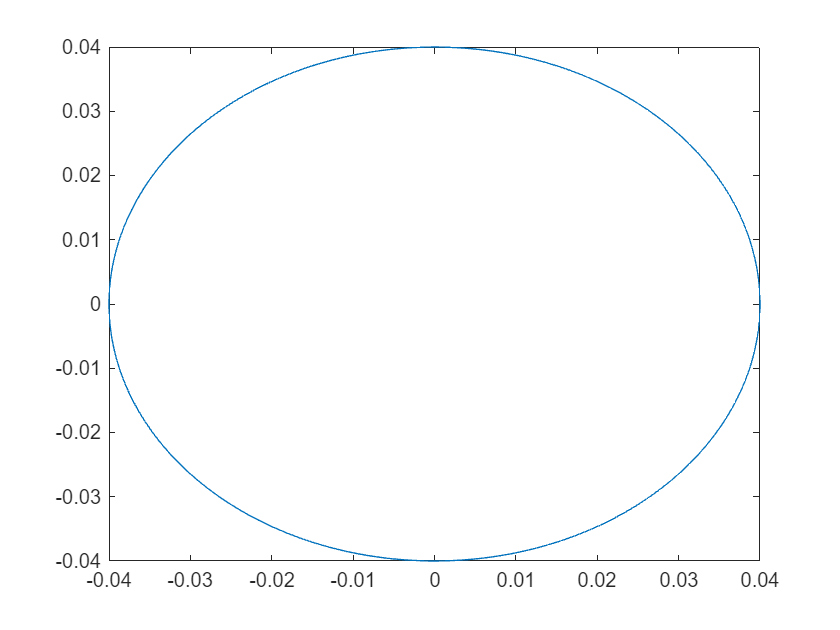

simplify(B.bx, "Steps", 1000);
simplify(B.by, "Steps", 1000);
fplot(A(1), A(2));
hold off;

fplot(B.bx(1), B.by(1));

BLAS: trying environment BLAS_VERSION...
BLAS: loading AOCL-LibBlis-Win-MT-dll.dll
BLAS: loaded AOCL-LibBlis-Win-MT-dll.dll@00007FFB14540000


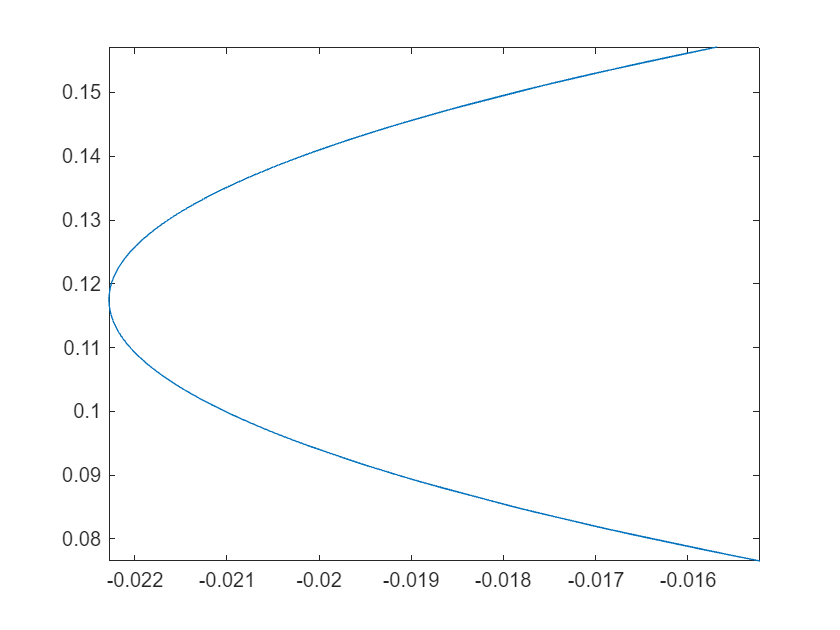

hold off;

B.bx(1)

$$ans = \begin{array}{l} \frac{\sigma_{4}+\sigma_{3}-461992725951977764135969368380689559}{811296384146066816957890051440640000\,\sigma_{1}}+\frac{\left(16\,\sin\left(\alpha \right)-47\right)\,\left(7626186010973028079404166483542016000\,\cos\left(\alpha \right)+901512542063109690512389482565912944\,\sin\left(\alpha \right)-1525237202194605615880833296708403200\,{\cos\left(\alpha \right)}^{2}+1525237202194605615880833296708403200\,{\sin\left(\alpha \right)}^{2}-519229685853482762853049632922009600\,{\sin\left(\alpha \right)}^{3}-519229685853482762853049632922009600\,{\cos\left(\alpha \right)}^{2}\,\sin\left(\alpha \right)-253530120045645880299340641075200000\,\sigma_{2}+101412048018258352119736256430080000\,\cos\left(\alpha \right)\,\sigma_{2}+2596148429267413814265248164610048000\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)-21713658119742954914390560313892409273\right)}{811296384146066816957890051440640000\,\sigma_{1}\,\left(256\,{\cos\left(\alpha \right)}^{2}-1280\,\cos\left(\alpha \right)+256\,{\sin\left(\alpha \right)}^{2}-1504\,\sin\left(\alpha \right)+3809\right)}\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(\alpha \right)-5\\ \sigma_{2}=\sqrt{\frac{\left(\sigma_{4}-162259276829213363391578010288128000\,\cos\left(\alpha \right)+\sigma_{3}-190654650274325701985104162088550400\,\sin\left(\alpha \right)+482476677679400661703151894763555991\right)\,\left(-\sigma_{4}+162259276829213363391578010288128000\,\cos\left(\alpha \right)-\sigma_{3}+190654650274325701985104162088550400\,\sin\left(\alpha \right)+688140311060428569363379265628124009\right)}{40173451106474756888549052308529065063055074844569820882534400000000}}\\ \sigma_{3}=32451855365842672678315602057625600\,{\sin\left(\alpha \right)}^{2}\\ \sigma_{4}=32451855365842672678315602057625600\,{\cos\left(\alpha \right)}^{2} \end{array}$$

B.by(1)

$$ans = \begin{array}{l} -\frac{7626186010973028079404166483542016000\,\cos\left(\alpha \right)+901512542063109690512389482565912944\,\sin\left(\alpha \right)-1525237202194605615880833296708403200\,{\cos\left(\alpha \right)}^{2}+1525237202194605615880833296708403200\,{\sin\left(\alpha \right)}^{2}-519229685853482762853049632922009600\,{\sin\left(\alpha \right)}^{3}-519229685853482762853049632922009600\,{\cos\left(\alpha \right)}^{2}\,\sin\left(\alpha \right)-253530120045645880299340641075200000\,\sigma_{1}+101412048018258352119736256430080000\,\cos\left(\alpha \right)\,\sigma_{1}+2596148429267413814265248164610048000\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)-21713658119742954914390560313892409273}{101412048018258352119736256430080000\,\left(256\,{\cos\left(\alpha \right)}^{2}-1280\,\cos\left(\alpha \right)+256\,{\sin\left(\alpha \right)}^{2}-1504\,\sin\left(\alpha \right)+3809\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{\left(\sigma_{3}-162259276829213363391578010288128000\,\cos\left(\alpha \right)+\sigma_{2}-190654650274325701985104162088550400\,\sin\left(\alpha \right)+482476677679400661703151894763555991\right)\,\left(-\sigma_{3}+162259276829213363391578010288128000\,\cos\left(\alpha \right)-\sigma_{2}+190654650274325701985104162088550400\,\sin\left(\alpha \right)+688140311060428569363379265628124009\right)}{40173451106474756888549052308529065063055074844569820882534400000000}}\\ \sigma_{2}=32451855365842672678315602057625600\,{\sin\left(\alpha \right)}^{2}\\ \sigma_{3}=32451855365842672678315602057625600\,{\cos\left(\alpha \right)}^{2} \end{array}$$

% eqH = [sqrt((hx - dx)^2 + (hy - dy)^2) == Lkp, sqrt((hx - B.bx(1))^2 + (hy - B.by(1)^2)) == H];
% 
% assume(B.bx(1), 'real');
% assume(B.by(1), 'real');
% 
% Hr = solve(eqH, [hx, hy], "Real", true, "ReturnConditions",true);

% Hr.hx

% Hr.hy

% fplot(A(1), A(2));
% hold on;
% fplot(B.bx(1), B.by(1));
% hold on;
% fplot(Hr.hx(1), Hr.hy(1));

theta = atan((B.by(1) - dy)/(B.bx(1) - dx));

simplify(theta, "Steps", 1000);

theta

var = 180*vpasolve(theta,alpha)

$$var = 71.225533074383497499249741834459$$

% Compute simplified symbolic expression
theta

simplifiedExpr = simplify(theta,"Steps",6400)

$$simplifiedExpr = \begin{array}{l} \mathrm{atan}\left(\frac{190654650274325701985104162088550400\,\cos\left(2\,\alpha \right)-162259276829213363391578010288128000\,\sin\left(2\,\alpha \right)+953273251371628509925520810442752000\,\cos\left(\alpha \right)+2192406783697123632367556423334979282\,\sin\left(\alpha \right)+31691265005705735037417580134400000\,\sigma_{1}-12676506002282294014967032053760000\,\cos\left(\alpha \right)\,\sigma_{1}-\frac{26724538965577918746199965866729926727}{8}}{1883607097481526950162959522505385682\,\cos\left(\alpha \right)+953273251371628509925520810442752000\,\sin\left(\alpha \right)-4056481920730334084789450257203200\,\sqrt{3809}\,\cos\left(2\,\alpha -\mathrm{atan}\left(\frac{47}{40}\right)\right)-37237236381704238668965656657920000\,\sigma_{1}+12676506002282294014967032053760000\,\sin\left(\alpha \right)\,\sigma_{1}-2843036060167863696404251687949992205}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{\left(162259276829213363391578010288128000\,\cos\left(\alpha \right)+190654650274325701985104162088550400\,\sin\left(\alpha \right)-514928533045243334381467496821181591\right)\,\left(162259276829213363391578010288128000\,\cos\left(\alpha \right)+190654650274325701985104162088550400\,\sin\left(\alpha \right)+655688455694585896685063663570498409\right)}{40173451106474756888549052308529065063055074844569820882534400000000}} \end{array}$$

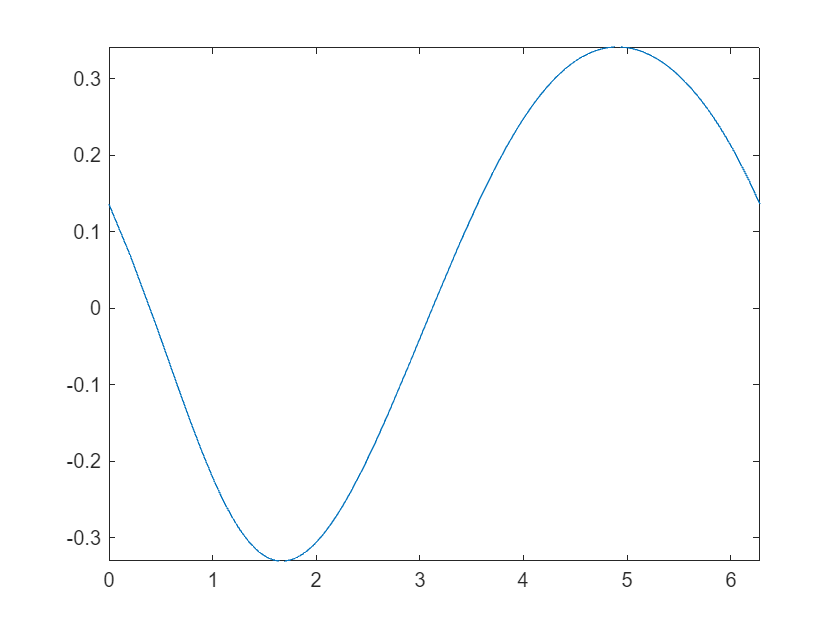

fplot(alpha, theta, [0, 2*pi]);

atan(H/Lkp)

ans = 0.1934

theta2 = theta - atan(H/Lkp)

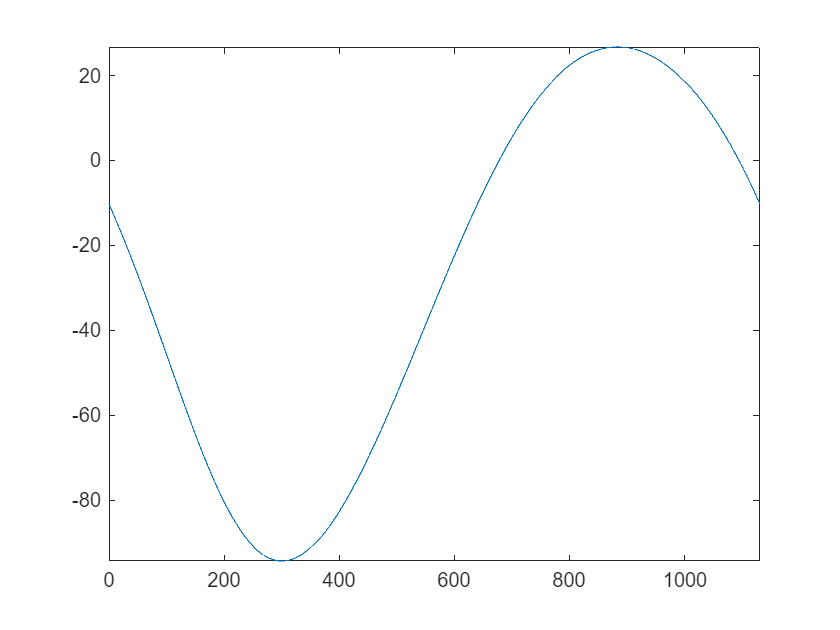

fplot(180*alpha, 180*theta2, [0, 2*pi], "MeshDensity",1500);


ansss = vpasolve(theta2, alpha)

$$ansss = -0.20367555386101219814795789488921$$


anB = [subs(B.bx(1), alpha, ansss), subs(B.by(1), alpha, ansss)]

$$anB = \left(\begin{array}{cc} -0.019999999999999996776100322075895 & 0.093999999999999999502839264578925 \end{array}\right)$$

anHy = anB(2) - 0.0080908107279476978142521701273746 - 0.0235

$$anHy = 0.062409189272052302227208797006242$$


anA = [subs(A(1), alpha, ansss), subs(A(2), alpha, ansss)]

$$anA = \left(\begin{array}{cc} 0.039173189578645832349213268680268 & -0.0080908107279476978142521701273746 \end{array}\right)$$

180*atan((subs(A(2), alpha, ansss) - anssss)/(subs(A(1), alpha, ansss) - anss))

$$ans = -188.19035223748389015378831808018$$